syms t(x,d,c)
t(x,d,c) = (sqrt(x^2+d^2)+d)/c

$$t(x, d, c) = \frac{d+\sqrt{d^{2}+x^{2}}}{c}$$

assume(-20e-3<=x & x<=20e-3)
assume(1450<=c & c<=1580)
assume(d<=50e-3)
basic_depth = 10e-3;%[m]
basic_sound_speed = 1580;%[m]
freq = 5e6;%[Hz]
syms d(c)
d(c) = basic_depth/basic_sound_speed*c

$$d(c) = \frac{934012358162509\,c}{147573952589676412928}$$

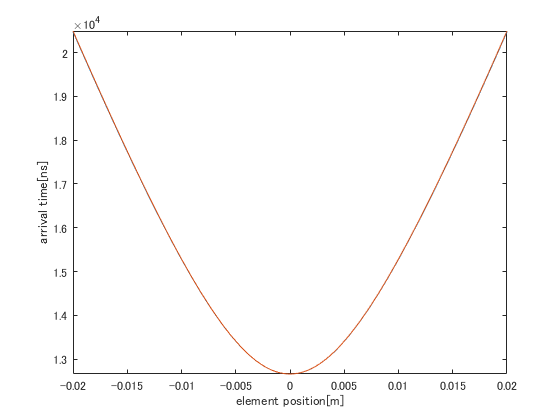

figure;
fplot(t(x,basic_depth,basic_sound_speed)*1e9)%[ns]
xlabel('element position[m]')
ylabel('arrival time[ns]')
hold on
differntial_sound_speed = 1578;
fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9)%[ns]
xlim([-20e-3 20e-3])
hold off

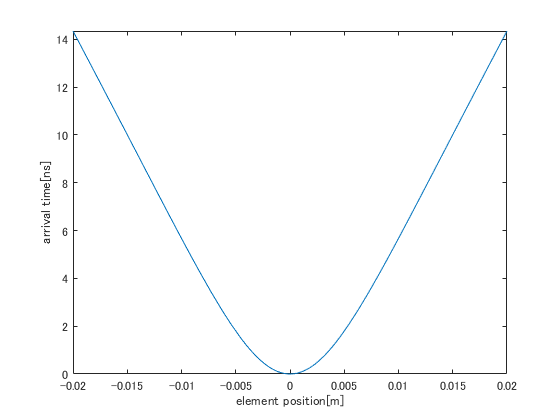

figure;
fplot(t(x,d(differntial_sound_speed),differntial_sound_speed)*1e9-t(x,d(basic_sound_speed),basic_sound_speed)*1e9);
xlabel('element position[m]')
ylabel('arrival time[ns]')
xlim([-20e-3 20e-3])

1/(freq)*1e9

ans = 200

time_36_degree = 1/(freq)*1e9/10

time_36_degree = 20

sampling_time = 1/(50e6)*1e9

sampling_time = 20

oversampling_time = sampling_time/4

約3 m/sの誤差であれば音速の推定可能性があると考えられる．

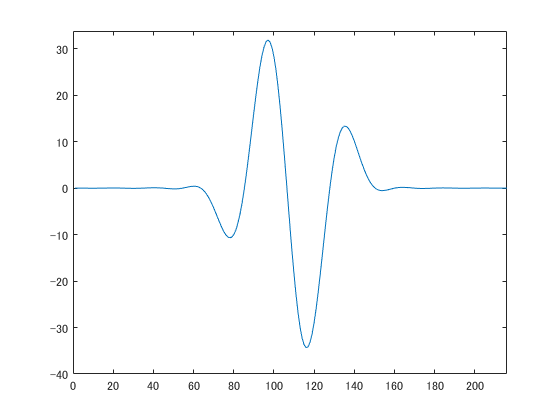

load("H:\data\kwave\result\2018_12_14_point_medium_various\boundary_2.0mm_IMCL4%\sourse_wave.mat")
load("H:\data\kwave\result\2018_12_14_point_medium_various\boundary_2.0mm_IMCL4%\kgrid.mat")
[~,num_sample] = size(source_wave);
% サンプル数を4倍にするためにスプライン補間
interp_sourcewave = interp1(source_wave,linspace(1,num_sample,num_sample*4)','spline');
figure;
plot(interp_sourcewave)
xlim([0 216])
ylim([-40.0 33.8])

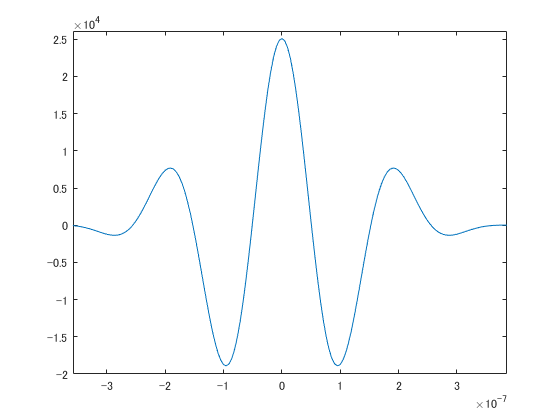

auto_correlation = xcorr(interp_sourcewave);
savefig()
exportfig()
figure;
interp_t = interp1(kgrid.t_array,linspace(1,num_sample,num_sample*4)','spline');
ind_inverse_t = linspace(length(interp_t),1,length(interp_t));
shift_t = cat(1,-interp_t(ind_inverse_t),interp_t(2:end));
plot(shift_t,auto_correlation);
xlim([-0.000000358 0.000000386])
ylim([-20000 26114])